# Chicken Ballistics

## Task 2

Solve the system of ODEs. 

Solve the system of ODEs by:

-  defining the time interval `tRange` from 0 to 3, 

-  defining the initial condition vector `Y0` such that the chicken starts at ground level with velocity 20 m/s, 

-  calling `ode45` and assigning the outputs to `tSol` and `YSol`. 

 Remember that your ODE function is defined in the function file `chicken.m`.

tRange=[0 5]

tRange =      0     5


Y0=[0 20]

Y0 =      0    20


[tSol,YSol]=ode45(@chicken,tRange,Y0)

tSol =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001


YSol =          0   20.0000
    0.0001   20.0000
    0.0001   20.0000
    0.0002   19.9999
    0.0002   19.9999
    0.0005   19.9998
    0.0007   19.9997
    0.0010   19.9995
    0.0012   19.9994
    0.0025   19.9988


## Task 3

Extract the vector representing the chicken's height from the solution matrix `YSol`, and assign it the variable `h`.

Plot the height as a function of time using the variables `tSol` and `h`.

Extract and plot the height.

h=YSol(:,1)

h =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


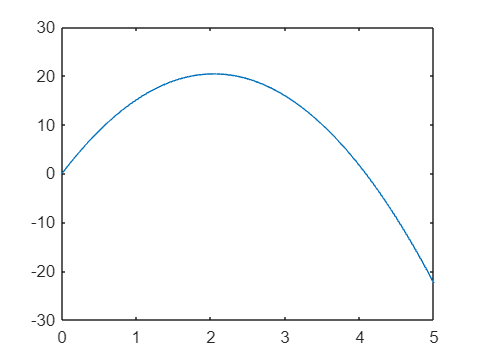

plot(tSol,h)

## Further Practice

Where does the chicken land? Conceptually it must occur when `h` `=` `0` and `t` `>` `0` but according to your plot that hasn't happened yet. There are several  approaches to determine the chicken landing time that you can try:

- **Graphical**: Set `tRange` `=` `[``0` `5``]` such that `h` becomes negative, then find out when `h` is close to zero by inspecting the plot.

- **Iterative**: Repeatedly vary the second element of `tRange` to solve the ODE system until the last element of `h` is close to zero. This process could be performed manually to fair accuracy or automated by a function such as `fzero` to achieve higher accuracy.

- **Statistical**: Repeat the graphical approach but perform a regression analysis to get an explicit equation for h(t).  

- **Events**: Use an [*event function*](https://www.mathworks.com/help/matlab/math/ode-event-location.html) to tell MATLAB to stop solving when `h` `=` `0`.

To try using an event function, open the script `chickenBallisticswEventFunction.mlx` using: 